clear
clc

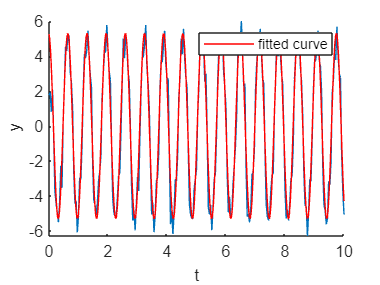

data = importdata("data\traveling-wave-experiment\without_skin_wave.txt");

t = data.data(:,1);
y_without = data.data(:,3);

figure()
hold on
plot(t,y_without+2)

period_guess = 1/(10/16/(2*pi));
mdl = fittype('a*sin(b*t+c)','indep','t');
[fittedmdl, gof, output] = fit(t,y_without+2,mdl,'start',[rand(),period_guess,rand()]);
plot(fittedmdl)
hold off


gof.rsquare

ans = 0.9514

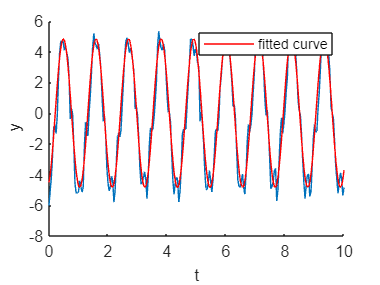

data = importdata("data\traveling-wave-experiment\with_skin_1.5mm_wave.txt");

t = data.data(:,1);
y15 = data.data(:,3);

figure()
hold on
plot(t,y15-6)

period_guess = 1/(10/10/(2*pi));
mdl1 = fittype('a*sin(b*t+c)','indep','t');
[fittedmdl15, gof, output] = fit(t,y15-6,mdl1,'start',[rand(),period_guess,2]);
plot(fittedmdl15)
hold off


gof.rsquare

ans = 0.9453

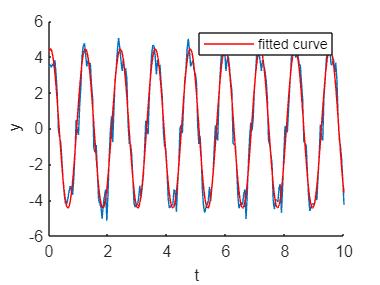

data = importdata("data\traveling-wave-experiment\with_skin_2.25mm_wave.txt");

t = data.data(:,1);
y225 = data.data(:,3);

figure()
hold on
plot(t,y225+3.5)

period_guess = 1/(10/9/(2*pi));
mdl1 = fittype('a*sin(b*t+c)','indep','t');
[fittedmdl225, gof, output] = fit(t,y225+3.5,mdl1,'start',[rand(),period_guess,rand()]);
plot(fittedmdl225)
hold off

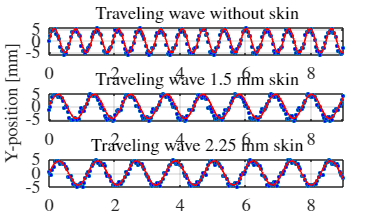

sine_without = @(t) fittedmdl.a*sin(fittedmdl.b*t);
sine_with15 = @(t) fittedmdl15.a*sin(fittedmdl15.b*t);
sine_with225 = @(t) fittedmdl225.a*sin(fittedmdl225.b*t);


fig = figure();
hold on
x0=10;
y0=10;
w=13;
h=7.5;
set(gcf,'units','centimeter','position',[x0,y0,w,h]);
subplot(3,1,1);
hold on
plot(t(1:end-12-11),y_without(13:end-11)+2,'o','MarkerFaceColor','b','MarkerSize',2)
plot(t(1:end-23),sine_without(t(1:end-23)),'r','LineWidth',1)
xlim([0 9])
set(gca,'TickLabelInterpreter','latex')
fontsize(11,'points')
grid on
box on
hold off
title('Traveling wave without skin','Interpreter','latex')
subplot(3,1,2);
hold on
plot(t(1:end-6-17),y15(7:end-17)-6,'o','MarkerFaceColor','b','MarkerSize',2)
plot(t(1:end-23),sine_with15(t(1:end-23)),'r','LineWidth',1)
xlim([0 9])
set(gca,'TickLabelInterpreter','latex')
fontsize(11,'points')
grid on
box on
hold off
title('Traveling wave 1.5 mm skin','Interpreter','latex')
fontsize(11,'points')
subplot(3,1,3);
hold on
plot(t(1:end-23),y225(24:end)+3.5,'o','MarkerFaceColor','b','MarkerSize',2)
plot(t(1:end-23),sine_with225(t(1:end-23)),'r','LineWidth',1)
xlim([0 9])
set(gca,'TickLabelInterpreter','latex')
fontsize(11,'points')
grid on
box on
hold off
title('Traveling wave 2.25 mm skin','Interpreter','latex')
xlabel('Time [s]','Interpreter','latex')
han=axes(fig,'visible','off');
han.YLabel.Visible='on';
ylabel('Y-position [mm]','Interpreter','latex')
set(gca,'TickLabelInterpreter','latex')
fontsize(11,'points')

theta_A = [fittedmdl.a fittedmdl15.a fittedmdl225.a];
CI_Ano = [5.153 5.453];
CI_A15 = [4.682 4.972];
CI_A225 = [4.322 4.557];

SE_Ano = (CI_Ano(2) - CI_Ano(1))/(2*1.96);
SE_A15 = (CI_A15(2) - CI_A15(1))/(2*1.96);
SE_A225 = (CI_A225(2) - CI_A225(1))/(2*1.96);

theta_f = [fittedmdl.b fittedmdl15.b fittedmdl225.b];
CI_fno = [9.654 9.674];
CI_f15 = [5.677 5.698];
CI_f225 = [5.294 5.312];

SE_fno = (CI_fno(2) - CI_fno(1))/(2*1.96);
SE_f15 = (CI_f15(2) - CI_f15(1))/(2*1.96);
SE_f225 = (CI_f225(2) - CI_f225(1))/(2*1.96);

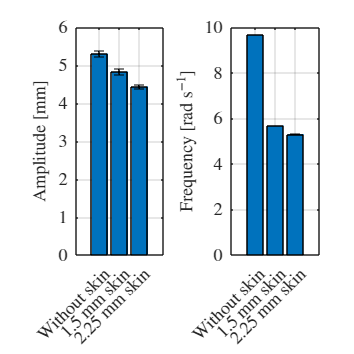

m = [fittedmdl.a fittedmdl15.a fittedmdl225.a];
s = [SE_Ano, SE_A15, SE_A225];
x = [.5 1 1.5];

b = figure;
figure(b);
hold on
subplot(1,2,1);
hold on
bar(x,m);
set(gca, 'XTickLabel', {'Without skin' '1.5 mm skin' '2.25 mm skin'});
set(gca, 'TickLabelInterpreter', 'latex')
set(gca,'XTick',x)
ylabel('Amplitude [mm]','Interpreter','latex')
fontsize(11,'points')
grid on
box on


er = errorbar(x,m,s);
er.Color = [0 0 0];
er.LineStyle = 'none';
hold off

m = [fittedmdl.b fittedmdl15.b fittedmdl225.b];
s = [SE_fno, SE_f15, SE_f225];
x = [.5 1 1.5];

subplot(1,2,2);
hold on
bar(x,m);
set(gca, 'XTickLabel', {'Without skin' '1.5 mm skin' '2.25 mm skin'});
set(gca, 'TickLabelInterpreter', 'latex')
set(gca,'XTick',x)
ylabel('Frequency [rad s$^{-1}$]','Interpreter','latex')
fontsize(11,'points')

er = errorbar(x,m,s);
er.Color = [0 0 0];
er.LineStyle = 'none';
hold off

x0=10;
y0=10;
w=7.5;
h=7.5;
set(gcf,'units','centimeter','position',[x0,y0,w,h]);
fontsize(11,'points')
grid on
box on

t_A_no_15 = (theta_A(1) - theta_A(2))/sqrt(SE_Ano^2 + SE_A15^2)

t_A_no_15 = 4.4712

p_value = 2 * (1 - tcdf(abs(t_A_no_15), 2))

p_value = 0.0466

t_A_no_225 = (theta_A(1) - theta_A(3))/sqrt(SE_Ano^2 + SE_A225^2)

t_A_no_225 = 8.8792

p_value = 2 * (1 - tcdf(abs(t_A_no_225), 2))

p_value = 0.0124

t_A_15_225 = (theta_A(2) - theta_A(3))/sqrt(SE_A15^2 + SE_A225^2)

t_A_15_225 = 4.0671

p_value = 2 * (1 - tcdf(abs(t_A_15_225), 2))

p_value = 0.0555


t_f_no_15 = (theta_f(1) - theta_f(2))/sqrt(SE_fno^2 + SE_f15^2)

t_f_no_15 = 537.5481

p_value = 2 * (1 - tcdf(abs(t_f_no_15), 2))

p_value = 3.4607e-06

t_f_no_225 = (theta_f(1) - theta_f(3))/sqrt(SE_fno^2 + SE_f225^2)

t_f_no_225 = 635.3427

p_value = 2 * (1 - tcdf(abs(t_f_no_225), 2))

p_value = 2.4773e-06

t_f_15_225 = (theta_f(2) - theta_f(3))/sqrt(SE_f15^2 + SE_f225^2)

t_f_15_225 = 54.4651

p_value = 2 * (1 - tcdf(abs(t_f_15_225), 2))

p_value = 3.3693e-04